# Image compression project report

## Team members:

- Ahmed Mohamed - 202200294

- Ahmed Salah - 202200212

### Section 1: How DFT and DCT works

    DFT and DCT are both relatively the same, but they differ in the way they treat the signal. Meaning, DFT takes the signal as periodic repeated signal which makes the computations of the frequencies a bit more complex, as high frequecy shifts in the signal (sharp edges or jumps) would be represented with a lot of high frequency sine waves. On the other hand, DCT is the solution of this problem as it treats the signal as periodic repeated but mirrored signal which eliminates the sharp jumps that were a problem in DFT. The complexity is reduced dramatically in DCT as it only requires to represent the signal with a bunch of low freq. cosine waves, hence the name Discrete Cosine Transform.

Equations of DFT and DCT:

    DFT : $X[m] = \sum_{n=0}^{N-1} x[n] \cdot e^{-j 2\pi mn / N}
$

    DCT : $X[m] =  \sum_{n=0}^{L-1} x[n] \cdot \cos\left(\frac{2 \pi nm}{L}\right)$

### Section 2: Implemention description

    Following the project desription, the work was divided as follows. First, loading the image folder , using multiple different photos as tests. Then resizing and converting to grayscale for simplicty in computation. Second, dividing the image to blocks, the cell data structure in matlab was used as we saw it was the best way to store the image blocks as it makes arthmatic operations easier to implement. Third, we implemented the DFT and DCT functions ourselves cause why not, then we computed the dft and dct for each block (8x8, 16x16, and 4x4). Fourth, we compared our reults with the built-in function in matlab to check if our implemention was accurate or not. Fifth, applying the comperssion algorithm with different retention ratios for all the blocks. Sixith, applied the inverse transformation on the compressed blocks. Seventh, reconstructiuon of the image from the inverse operation.

Every step is explained in details before each section with commented code.

### Section 3: Helper Functions

#### *Don't run the code in this section*

1D DFT:

function [out] = DFT(x)
%DFT Summary of this function goes here
%   the functions performs a simple   
%   1D-DFT transformation for the
%   input signal

% Summation length
N = length(x);

% transformed matrix = zeros(1, N);
out = zeros(1,N);

% Perform the DFT calculation
for m = 0:N-1
    for n = 0:N-1
        out(m+1) = out(m+1) + x(n+1) * exp(-2*pi*1i*m*n/N);
    end
end
end

2D DFT

function [out] = DFT2(X)
%DFT2 Summary of this function goes here
%   Detailed explanation goes here
arguments (Input)
    X
end

arguments (Output)
    out
end

[n1,n2] = size(X);

out = zeros(n1,n2);

for row = 1:n1
    out(row,:) = DFT(X(row,:));
end

for col = 1:n2
    out(:,col) = DFT(out(:,col));
end

end

1D IDFT

function [out] = IDFT(X)
%IDFT Summary of this function goes here
%   This function performs a simple 1D-Inverse DFT transformation for the
%   input frequency domain signal.

N = length(X);
out = zeros(1, N);

for n = 0:N-1
    for k = 0:N-1
        out(n+1) = out(n+1) + X(k+1) * exp(2*pi*1i*k*n/N);
    end
end

% Apply the final 1/N scaling factor
out = out / N;

end

2D IDFT

function [out] = IDFT2(X)
%IDFT2 Summary of this function goes here
%   This function performs a 2D-Inverse DFT by applying 1D-IDFT to rows
%   and then to columns.

arguments (Input)
    X
end

arguments (Output)
    out
end

[n1, n2] = size(X);
out = zeros(n1, n2);

% Apply 1D IDFT to each row
for row = 1:n1
    out(row, :) = IDFT(X(row, :));
end

% Apply 1D IDFT to each column of the intermediate result
for col = 1:n2
    out(:, col) = IDFT(out(:, col));
end

end

1D DCT

function [out] = DCT(x)
%DCT Summary of this function goes here
%   This function performs a 1D Discrete Cosine Transform (Type-II) for the
%   input signal. This is the standard version used in JPEG compression.

N = length(x);
out = zeros(1, N);

% Perform the DCT calculation
for k = 0:N-1
    sum_val = 0;
    for n = 0:N-1
        sum_val = sum_val + x(n+1) * cos(pi * (n + 0.5) * k / N);
    end
    
    % Apply the scaling factor c(k)
    if k == 0
        % c(0) = sqrt(1/N)
        out(k+1) = sum_val * sqrt(1/N);
    else
        % c(k) = sqrt(2/N) for k > 0
        out(k+1) = sum_val * sqrt(2/N);
    end
end

end

2D DCT

function [out] = DCT2(X)
%DCT2 Summary of this function goes here
%   This function performs a 2D Discrete Cosine Transform by applying 1D-DCT
%   to rows and then to columns.

arguments (Input)
    X
end

arguments (Output)
    out
end

[n1, n2] = size(X);
out = zeros(n1, n2);

% Apply 1D DCT to each row
for row = 1:n1
    out(row, :) = DCT(X(row, :));
end

% Apply 1D DCT to each column of the intermediate result
for col = 1:n2
    out(:, col) = DCT(out(:, col));
end

end

1D IDCT

function [out] = IDCT(X)
%IDCT Summary of this function goes here
%   This function performs a 1D Inverse Discrete Cosine Transform (Type-III),
%   which is the inverse of the DCT Type-II used above.

N = length(X);
out = zeros(1, N);

% Perform the IDCT calculation
for n = 0:N-1
    sum_val = 0;
    for k = 0:N-1
        % The scaling factor c(k) is now inside the summation
        if k == 0
            c_k = sqrt(1/N);
        else
            c_k = sqrt(2/N);
        end
        sum_val = sum_val + c_k * X(k+1) * cos(pi * (n + 0.5) * k / N);
    end
    out(n+1) = sum_val;
end

end

2D IDCT

function [out] = IDCT2(X)
%IDCT2 Summary of this function goes here
%   This function performs a 2D Inverse Discrete Cosine Transform by applying
%   1D-IDCT to rows and then to columns.

arguments (Input)
    X
end

arguments (Output)
    out
end

[n1, n2] = size(X);
out = zeros(n1, n2);

% Apply 1D IDCT to each row
for row = 1:n1
    out(row, :) = IDCT(X(row, :));
end

% Apply 1D IDCT to each column of the intermediate result
for col = 1:n2
    out(:, col) = IDCT(out(:, col));
end

end

Compress functions "Coefficient reduction"

function compressedBlocks = compressBlocks(transformedBlocks, retentionRatio)
%COMPRESSBLOCKS Reduces coefficients in each block for compression.
%
%   Takes a cell array of transformed blocks (DFT or DCT) and a retention
%   ratio (e.g., 0.25 for 25%) and returns a new cell array where each
%   block has been compressed by zeroing out all but the largest
%   coefficients by magnitude.
%
% Inputs:
%   transformedBlocks - Cell array of 2D matrices (transform coefficients).
%   retentionRatio    - Scalar between 0 and 1, the fraction of coefficients to keep.
%
% Output:
%   compressedBlocks  - Cell array of compressed coefficient matrices.

    % Use cellfun to apply the compression logic to each block in the cell array
    compressedBlocks = cellfun(@(block) compress_single_block(block, retentionRatio), ...
                              transformedBlocks, ...
                              'UniformOutput', false);

end

function compressed_block = compress_single_block(block, retentionRatio)
    % Get block dimensions
    [M, N] = size(block);
    totalCoeffs = M * N;

    % Calculate the exact number of coefficients to keep
    k = floor(totalCoeffs * retentionRatio);

    % If k is 0, return a zero matrix of the same size and data type
    if k == 0
        compressed_block = zeros(M, N, 'like', block);
        return;
    end

    % Find the magnitude threshold. We need to find the k-th largest magnitude.
    % 1. Get the magnitude of all coefficients and flatten to a vector.
    mag_vec = abs(block(:));
    % 2. Sort the magnitudes in descending order.
    sorted_mag = sort(mag_vec, 'descend');
    % 3. The threshold is the magnitude of the k-th largest coefficient.
    threshold = sorted_mag(k);

    % Create a logical mask. 'true' for coefficients to keep, 'false' for zeroing.
    % We keep coefficients with a magnitude greater than or equal to the threshold.
    mask = abs(block) >= threshold;

    % Apply the mask to the original block to zero out the rest.
    compressed_block = block .* mask;
end

Compare with built-in function

function report = compareTransform(originalBlocks, customTransformedBlocks, transformType)
%COMPARETRANSFORM Compares a custom transform against MATLAB's built-in function.
%
%   report = compareTransform(originalBlocks, customTransformedBlocks, 'dft')
%   Compares each block in 'customTransformedBlocks' (from your DFT2) with
%   the result of MATLAB's built-in fft2 on the corresponding block in
%   'originalBlocks'.
%
%   report = compareTransform(originalBlocks, customTransformedBlocks, 'dct')
%   Compares each block in 'customTransformedBlocks' (from your DCT2) with
%   the result of MATLAB's built-in dct2 on the corresponding block in
%   'originalBlocks'.
%
% Inputs:
%   originalBlocks        - Cell array of original image blocks (e.g., blocks8).
%   customTransformedBlocks - Cell array of blocks transformed by your custom function.
%   transformType         - String, either 'dft' or 'dct'.
%
% Output:
%   report                - A cell array of structures, where each structure
%                           contains error metrics for a corresponding block.

% Validate the transform type input
if ~strcmpi(transformType, 'dft') && ~strcmpi(transformType, 'dct')
    error('Invalid transformType. Please use ''dft'' or ''dct''.');
end

% Get dimensions of the block grid
[numRows, numCols] = size(originalBlocks);

% Pre-allocate the report cell array
report = cell(numRows, numCols);

% Determine the reference MATLAB function based on the input type
switch lower(transformType)
    case 'dft'
        referenceFunc = @fft2;
    case 'dct'
        referenceFunc = @dct2;
end

% Loop through each block and compare
for r = 1:numRows
    for c = 1:numCols
        
        % Get the custom transformed block
        customBlock = customTransformedBlocks{r, c};
        
        % Get the reference block using MATLAB's built-in function
        originalBlock_double = double(originalBlocks{r, c});
        matlabBlock = referenceFunc(originalBlock_double);
        
        % --- Calculate Error Metrics ---
        
        % Absolute difference
        diff = customBlock - matlabBlock;
        
        % Maximum absolute error
        maxAbsError = max(abs(diff(:)));
        
        % Root Mean Square (RMS) error
        rmsError = sqrt(mean(abs(diff(:)).^2));
        
        % Maximum magnitude error
        magError = abs(abs(customBlock(:)) - abs(matlabBlock(:)));
        maxMagError = max(magError);
        
        % Phase error (less relevant for DCT but included for consistency)
        phaseError = angle(customBlock(:)) - angle(matlabBlock(:));
        phaseErrorStd = std(phaseError);
        
        % Relative error
        relError = norm(diff(:)) / norm(matlabBlock(:));
        
        % Store the results in a structure
        report{r, c} = struct(...
            'maxAbsError', maxAbsError, ...
            'rmsError', rmsError, ...
            'maxMagError', maxMagError, ...
            'phaseErrorStd', phaseErrorStd, ...
            'relError', relError ...
        );
    end
end
end

Bonus helper function

function vec = zigzagScan(block)
%ZIGZAGSCAN Summary of this function goes here
%   Detailed explanation goes here
% Simple zigzag scanning using MATLAB's natural indexing
    n = size(block, 1);
    vec = [];
    
    % Scan diagonals
    for s = 2:2*n
        if mod(s, 2) == 0
            % Even diagonal - go up
            for i = max(1, s-n):min(s-1, n)
                j = s - i;
                vec = [vec, block(i, j)];
            end
        else
            % Odd diagonal - go down
            for i = min(s-1, n):-1:max(1, s-n)
                j = s - i;
                vec = [vec, block(i, j)];
            end
        end
    end
end

clc; clear;

### Section 4: Compression Workflow

###     SubSection 1: load images and preprocessing


% Load image folders
imageFolder = 'D:\Fall forth year\Digital Signal Processing\project\images';
imageFiles = dir(fullfile(imageFolder));

% select the desired image
imageFileName = imageFiles(4).name;
imagePath = fullfile(imageFolder, imageFileName);

% Read the image
imageData = imread(imagePath)

imageData = 1800×1500×3 uint8 array
imageData(:,:,1) =

     3     3     3     3     3     3     3     3     0     0     0     2     5    10    14    17    12    12    12    11    11    10    10    10     2     3     3     4     6     7     7     8     6     5     5     4     2     1     1     0     2     2     2     2     2     2     2     2     3     3     3     3     3     3     3     3     2     2     2     2     2     2     2     2     4     4     4     4     4     4     4     4     5     5     5     5     5     5     5     5     0     4     8    12    12     8     4     0    44   130   220   254   253   252   254   253   252   253   253   253   253   252   251   250   252   252   252   252   252   252   252   252   248   249   250   251   253   254   255   255   255   254   251   249   249   250   252   254   255   255   252   247   210   112    24     3    17    10    18    14    14    16     0     0     7     6     4     3     3     4     6     7     8     8     8     8     8  

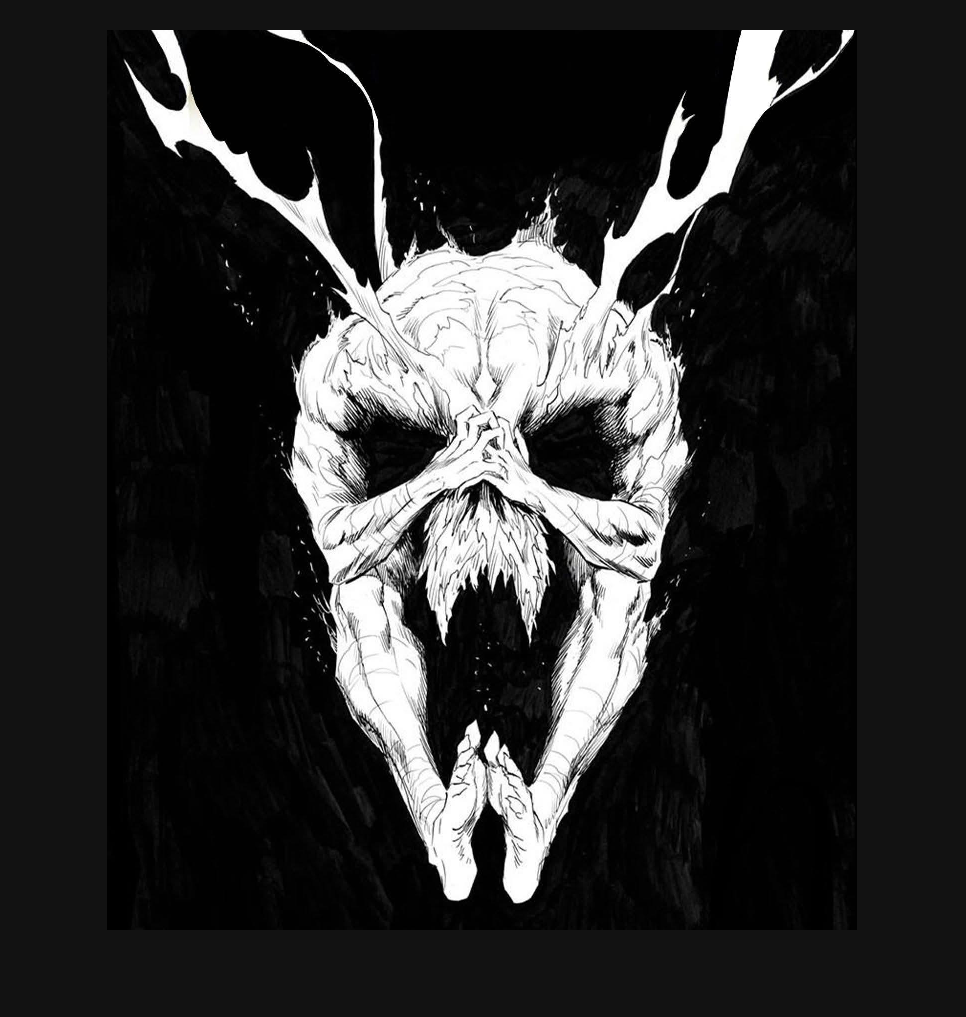

% show image
figure;
imshow(imageData);

% Convert the image to grayscale
grayImageData = rgb2gray(imageData)

grayImageData = 1800×1500 uint8 matrix
    3    3    3    3    3    3    3    3    0    0    0    2    5   10   14   17   12   12   12   11   11   10   10   10    2    3    3    4    6    7    7    8    6    5    5    4    2    1    1    0    2    2    2    2    2    2    2    2    3    3
    3    3    3    3    3    3    3    3    1    0    1    2    5    9   13   16   13   13   12   11   11   10   10    9    3    3    4    5    5    6    7    7    5    5    4    3    3    2    1    1    2    2    2    2    2    2    2    2    3    3
    3    3    3    3    3    3    3    3    1    1    1    2    5    8   12   15   14   14   13   12   11   10    9    9    3    4    4    5    5    6    6    7    5    4    4    3    3    2    2    1    2    2    2    2    2    2    2    2    3    3
    4    4    4    4    4    4    4    4    2    1    1    2    4    7   11   13   15   15   14   12   11   10    9    8    4    5    5    5    5    5    5    6    4    3    3    3    3    3    3    2    2   

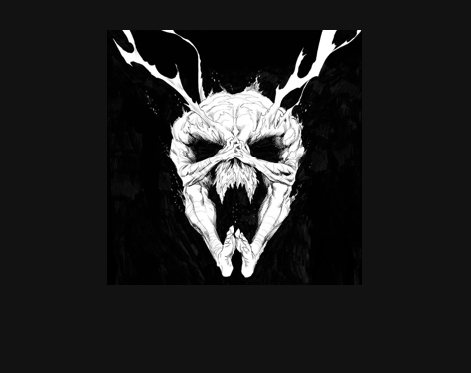


% resize to 256x256
resizedImageData = imresize(grayImageData, [256 256]);
imshow(resizedImageData);

###     SubSection 2: Blocks

- 8x8 blocks

% Divide the image into 8x8 blocks
blockSize = 8;
numBlocks = size(resizedImageData) / blockSize;
blocks8 = mat2cell(resizedImageData, repmat(blockSize, 1, numBlocks(1)), repmat(blockSize, 1, numBlocks(2)));

- 16x16 blocks

blockSize = 16;
numBlocks = size(resizedImageData) / blockSize;
blocks16 = mat2cell(resizedImageData, repmat(blockSize, 1, numBlocks(1)), repmat(blockSize, 1, numBlocks(2)));

- 4x4 blocks 

blockSize = 4;
numBlocks = size(resizedImageData) / blockSize;
blocks4 = mat2cell(resizedImageData, repmat(blockSize, 1, numBlocks(1)), repmat(blockSize, 1, numBlocks(2)));

###     SubSection 3: DFT and DCT

- DFT

dftBlocks16 = cellfun(@(block) DFT2(double(block)), blocks16, 'UniformOutput', false);
dftBlocks4 = cellfun(@(block) DFT2(double(block)), blocks4, 'UniformOutput', false);
dftBlocks8 = cellfun(@(block) DFT2(double(block)), blocks8, 'UniformOutput', false);

- DCT

dctBlocks16 = cellfun(@(block) DCT2(double(block)), blocks16, 'UniformOutput', false);
dctBlocks4 = cellfun(@(block) DCT2(double(block)), blocks4, 'UniformOutput', false);
dctBlocks8 = cellfun(@(block) DCT2(double(block)), blocks8, 'UniformOutput', false);

###     SubSection 4: compare

reportDFT = compareTransform(blocks8,dftBlocks8,'dft');
disp(reportDFT{1});

      maxAbsError: 1.7083e-13
         rmsError: 5.1159e-14
      maxMagError: 1.7053e-13
    phaseErrorStd: 1.1019
         relError: 1.1044e-15



reportDCT = compareTransform(blocks8,dctBlocks8,'dct');
reportDCT{1}

ans = struct with fields:
      maxAbsError: 5.1653e-14
         rmsError: 1.0819e-14
      maxMagError: 5.1653e-14
    phaseErrorStd: 0
         relError: 1.8684e-15


###     SubSection 5: Compression (Coefficient reduction)

Define the retention ratios we want to test

retentionRatios = [0.10, 0.25, 0.50];


Compress DCT blocks

compressedDCT8_10 = compressBlocks(dctBlocks8, retentionRatios(1)); % 10% retention
compressedDCT8_25 = compressBlocks(dctBlocks8, retentionRatios(2)); % 25% retention
compressedDCT8_50 = compressBlocks(dctBlocks8, retentionRatios(3)); % 50% retention


Compress DFT blocks

compressedDFT8_10 = compressBlocks(dftBlocks8, retentionRatios(1)); % 10% retention
compressedDFT8_25 = compressBlocks(dftBlocks8, retentionRatios(2)); % 25% retention
compressedDFT8_50 = compressBlocks(dftBlocks8, retentionRatios(3)); % 50% retention


Visualization of a compressed block before and after

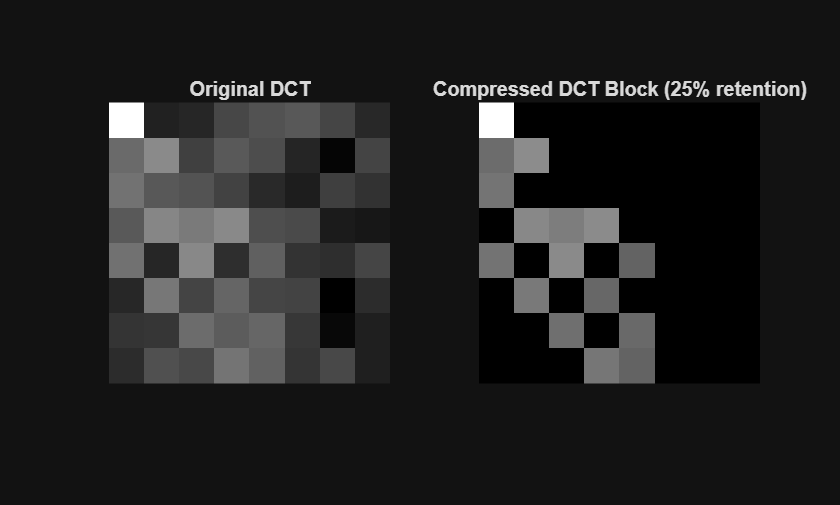

originalDCTBlock = dctBlocks8{16, 16};
compressedDCTBlock = compressedDCT8_25{16, 16};

figure;
subplot(1, 2, 1);
imshow(log(1 + abs(originalDCTBlock)), []);
title('Original DCT');

subplot(1, 2, 2);
imshow(log(1 + abs(compressedDCTBlock)), []);
title('Compressed DCT Block (25% retention)');

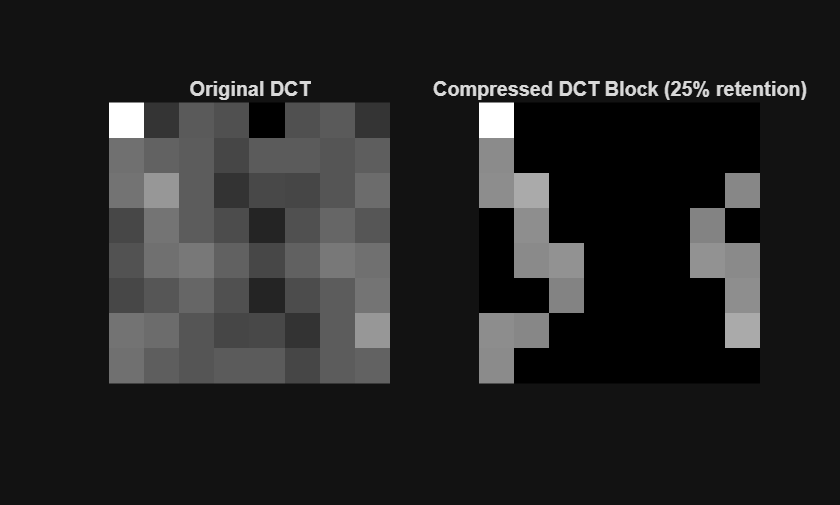

originalDFTBlock = dftBlocks8{16, 16};
compressedDFTBlock = compressedDFT8_25{16, 16};

figure;
subplot(1, 2, 1);
imshow(log(1 + abs(originalDFTBlock)), []);
title('Original DCT');

subplot(1, 2, 2);
imshow(log(1 + abs(compressedDFTBlock)), []);
title('Compressed DCT Block (25% retention)');

###     SubSection 6: Reconstruction

- Reconstruct from DCT

reconstructedDCT8_50 = cellfun(@(block) IDCT2(block), compressedDCT8_50, 'UniformOutput', false);
reconstructedImageDCT8_50 = cell2mat(reconstructedDCT8_50);

reconstructedDCT8_25 = cellfun(@(block) IDCT2(block), compressedDCT8_25, 'UniformOutput', false);
reconstructedImageDCT8_25 = cell2mat(reconstructedDCT8_25);

reconstructedDCT8_10 = cellfun(@(block) IDCT2(block), compressedDCT8_10, 'UniformOutput', false);
reconstructedImageDCT8_10 = cell2mat(reconstructedDCT8_10);

- Reconstruct from DFT

reconstructedDFT8_50 = cellfun(@(block) IDFT2(block), compressedDFT8_50, 'UniformOutput', false);
reconstructedImageDFT8_50 = cell2mat(reconstructedDFT8_50);

reconstructedDFT8_25 = cellfun(@(block) IDFT2(block), compressedDFT8_25, 'UniformOutput', false);
reconstructedImageDFT8_25 = cell2mat(reconstructedDFT8_25);

reconstructedDFT8_10 = cellfun(@(block) IDFT2(block), compressedDFT8_10, 'UniformOutput', false);
reconstructedImageDFT8_10 = cell2mat(reconstructedDFT8_10);


Note: The output of IDFT2 and IDCT2 might be complex due to floating-point errors.

You should take the real part before displaying.

reconstructedImageDFT8_50 = real(reconstructedImageDFT8_50);
reconstructedImageDCT8_50 = real(reconstructedImageDCT8_50);

Original vs DCT 50% vs DFT 50%

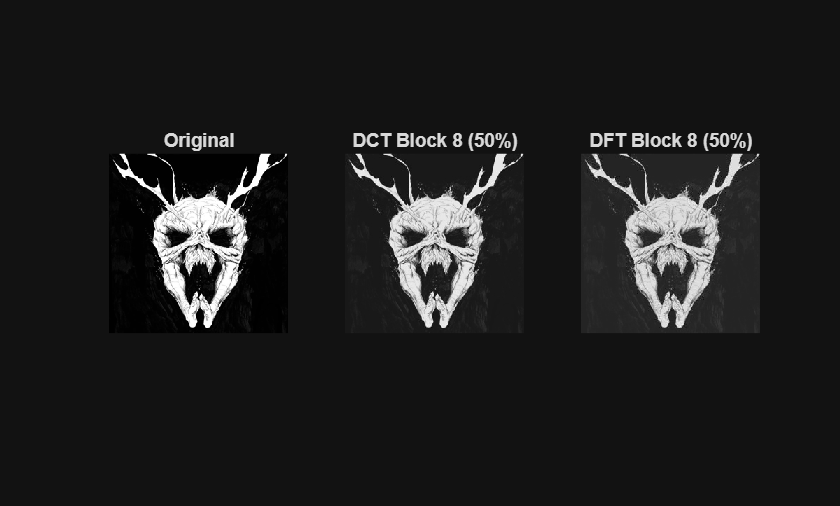

figure;

subplot(1, 3, 1);
imshow(resizedImageData, []);
title('Original');

subplot(1, 3, 2);
imshow(reconstructedImageDCT8_50, []);
title('DCT Block 8 (50%)');

subplot(1, 3, 3);
imshow(reconstructedImageDFT8_50, []);
title('DFT Block 8 (50%)');

- same for 4x4

Compress DCT blocks

compressedDCT4_10 = compressBlocks(dctBlocks4, retentionRatios(1)); % 10% retention
compressedDCT4_25 = compressBlocks(dctBlocks4, retentionRatios(2)); % 25% retention
compressedDCT4_50 = compressBlocks(dctBlocks4, retentionRatios(3)); % 50% retention


Compress DFT blocks

compressedDFT4_10 = compressBlocks(dftBlocks4, retentionRatios(1)); % 10% retention
compressedDFT4_25 = compressBlocks(dftBlocks4, retentionRatios(2)); % 25% retention
compressedDFT4_50 = compressBlocks(dftBlocks4, retentionRatios(3)); % 50% retention


Reconstruct from DCT

reconstructedDCT4_50 = cellfun(@(block) IDCT2(block), compressedDCT4_50, 'UniformOutput', false);
reconstructedImageDCT4_50 = cell2mat(reconstructedDCT4_50);

reconstructedDCT4_25 = cellfun(@(block) IDCT2(block), compressedDCT4_25, 'UniformOutput', false);
reconstructedImageDCT4_25 = cell2mat(reconstructedDCT4_25);

reconstructedDCT4_10 = cellfun(@(block) IDCT2(block), compressedDCT4_10, 'UniformOutput', false);
reconstructedImageDCT4_10 = cell2mat(reconstructedDCT4_10);


Reconstruct from DFT

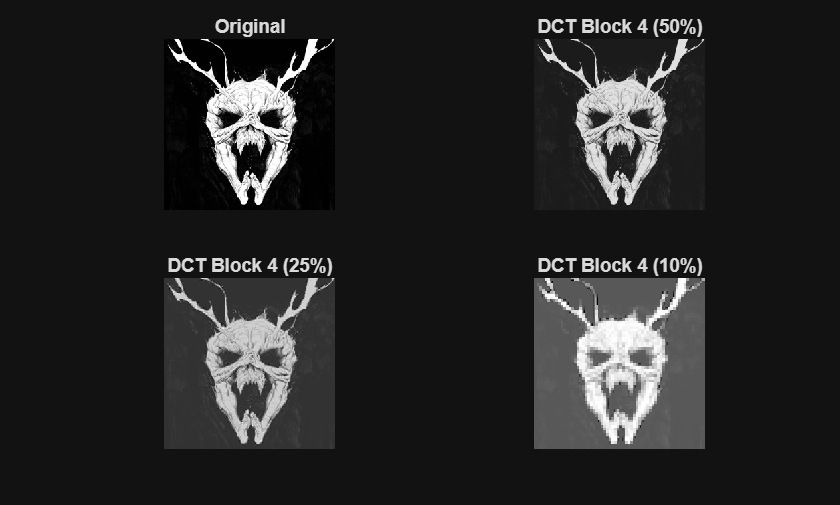

reconstructedDFT4_50 = cellfun(@(block) IDFT2(block), compressedDFT4_50, 'UniformOutput', false);
reconstructedImageDFT4_50 = cell2mat(reconstructedDFT4_50);

reconstructedDFT4_25 = cellfun(@(block) IDFT2(block), compressedDFT4_25, 'UniformOutput', false);
reconstructedImageDFT4_25 = cell2mat(reconstructedDFT4_25);

reconstructedDFT4_10 = cellfun(@(block) IDFT2(block), compressedDFT4_10, 'UniformOutput', false);
reconstructedImageDFT4_10 = cell2mat(reconstructedDFT4_10);

reconstructedImageDCT4_50 = real(reconstructedImageDCT4_50);
reconstructedImageDCT4_25 = real(reconstructedImageDCT4_25);
reconstructedImageDCT4_10 = real(reconstructedImageDCT4_10);

reconstructedImageDFT4_50 = real(reconstructedImageDFT4_50);
reconstructedImageDFT4_25 = real(reconstructedImageDFT4_25);
reconstructedImageDFT4_10 = real(reconstructedImageDFT4_10);

% Display DCT results for 4x4 blocks
figure;
subplot(2, 2, 1);
imshow(resizedImageData, []);
title('Original');

subplot(2, 2, 2);
imshow(reconstructedImageDCT4_50, []);
title('DCT Block 4 (50%)');

subplot(2, 2, 3);
imshow(reconstructedImageDCT4_25, []);
title('DCT Block 4 (25%)');

subplot(2, 2, 4);
imshow(reconstructedImageDCT4_10, []);
title('DCT Block 4 (10%)');

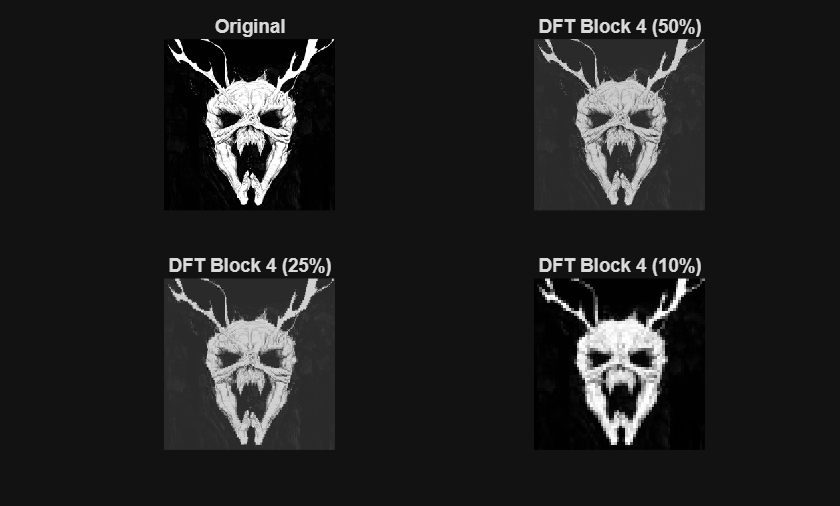


figure;
subplot(2, 2, 1);
imshow(resizedImageData, []);
title('Original');

subplot(2, 2, 2);
imshow(reconstructedImageDFT4_50, []);
title('DFT Block 4 (50%)');

subplot(2, 2, 3);
imshow(reconstructedImageDFT4_25, []);
title('DFT Block 4 (25%)');

subplot(2, 2, 4);
imshow(reconstructedImageDFT4_10, []);
title('DFT Block 4 (10%)');

- 16x16

Compress DCT blocks

compressedDCT16_10 = compressBlocks(dctBlocks16, retentionRatios(1)); % 10% retention
compressedDCT16_25 = compressBlocks(dctBlocks16, retentionRatios(2)); % 25% retention
compressedDCT16_50 = compressBlocks(dctBlocks16, retentionRatios(3)); % 50% retention

Compress DFT blocks

compressedDFT16_10 = compressBlocks(dftBlocks16, retentionRatios(1)); % 10% retention
compressedDFT16_25 = compressBlocks(dftBlocks16, retentionRatios(2)); % 25% retention
compressedDFT16_50 = compressBlocks(dftBlocks16, retentionRatios(3)); % 50% retention

Reconstruct from DCT

reconstructedDCT16_50 = cellfun(@(block) IDCT2(block), compressedDCT16_50, 'UniformOutput', false);
reconstructedImageDCT16_50 = cell2mat(reconstructedDCT16_50);

reconstructedDCT16_25 = cellfun(@(block) IDCT2(block), compressedDCT16_25, 'UniformOutput', false);
reconstructedImageDCT16_25 = cell2mat(reconstructedDCT16_25);

reconstructedDCT16_10 = cellfun(@(block) IDCT2(block), compressedDCT16_10, 'UniformOutput', false);
reconstructedImageDCT16_10 = cell2mat(reconstructedDCT16_10);

Reconstruct from DFT

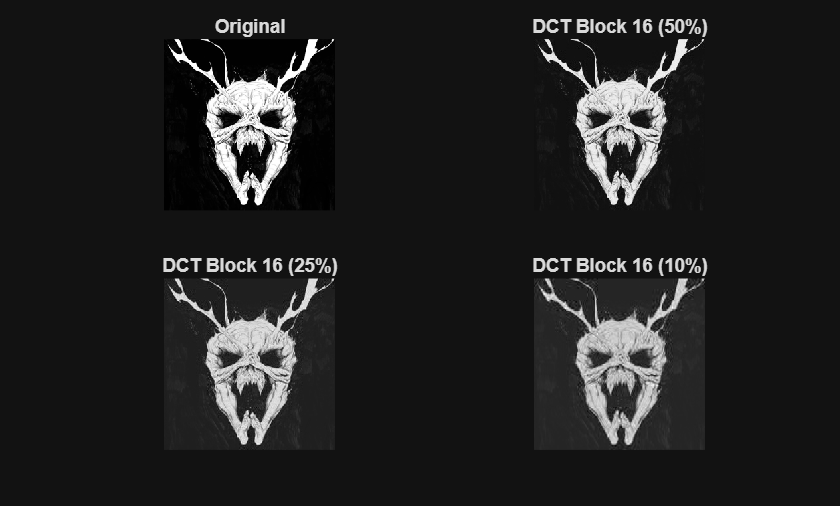

reconstructedDFT16_50 = cellfun(@(block) IDFT2(block), compressedDFT16_50, 'UniformOutput', false);
reconstructedImageDFT16_50 = cell2mat(reconstructedDFT16_50);

reconstructedDFT16_25 = cellfun(@(block) IDFT2(block), compressedDFT16_25, 'UniformOutput', false);
reconstructedImageDFT16_25 = cell2mat(reconstructedDFT16_25);

reconstructedDFT16_10 = cellfun(@(block) IDFT2(block), compressedDFT16_10, 'UniformOutput', false);
reconstructedImageDFT16_10 = cell2mat(reconstructedDFT16_10);


reconstructedImageDCT16_50 = real(reconstructedImageDCT16_50);
reconstructedImageDCT16_25 = real(reconstructedImageDCT16_25);
reconstructedImageDCT16_10 = real(reconstructedImageDCT16_10);

reconstructedImageDFT16_50 = real(reconstructedImageDFT16_50);
reconstructedImageDFT16_25 = real(reconstructedImageDFT16_25);
reconstructedImageDFT16_10 = real(reconstructedImageDFT16_10);

% Display DCT results for 16x16 blocks
figure;
subplot(2, 2, 1);
imshow(resizedImageData, []);
title('Original');

subplot(2, 2, 2);
imshow(reconstructedImageDCT16_50, []);
title('DCT Block 16 (50%)');

subplot(2, 2, 3);
imshow(reconstructedImageDCT16_25, []);
title('DCT Block 16 (25%)');

subplot(2, 2, 4);
imshow(reconstructedImageDCT16_10, []);
title('DCT Block 16 (10%)');

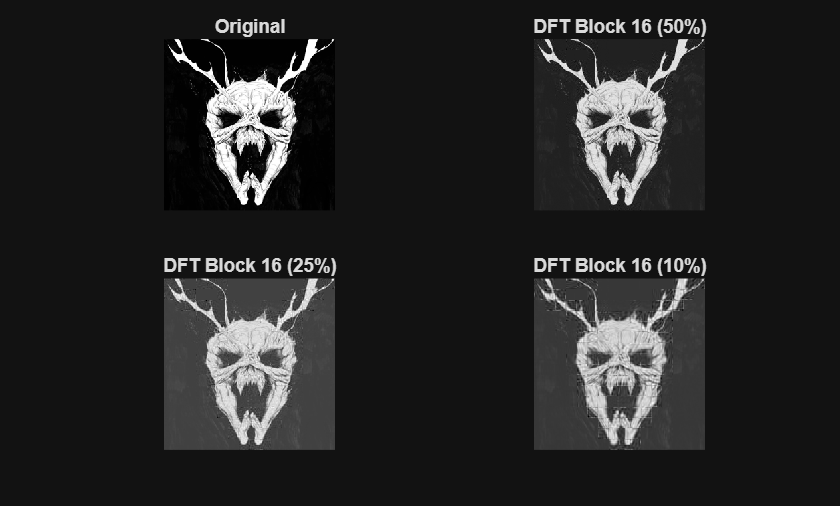


% Display DFT results for 16x16 blocks
figure;
subplot(2, 2, 1);
imshow(resizedImageData, []);
title('Original');

subplot(2, 2, 2);
imshow(reconstructedImageDFT16_50, []);
title('DFT Block 16 (50%)');

subplot(2, 2, 3);
imshow(reconstructedImageDFT16_25, []);
title('DFT Block 16 (25%)');

subplot(2, 2, 4);
imshow(reconstructedImageDFT16_10, []);
title('DFT Block 16 (10%)');

### Section 5: Analysis

-  Define a function to calculate Mean Squared Error (MSE) , This function handles that by scaling images to the range [0, 1].

calculateMSE = @(original, reconstructed) mean((double(original(:))/255 - double(reconstructed(:))/255).^2);

% For 4x4 blocks
mseDCT4_10 = calculateMSE(resizedImageData, reconstructedImageDCT4_10);
mseDCT4_25 = calculateMSE(resizedImageData, reconstructedImageDCT4_25);
mseDCT4_50 = calculateMSE(resizedImageData, reconstructedImageDCT4_50);

mseDFT4_10 = calculateMSE(resizedImageData, reconstructedImageDFT4_10);
mseDFT4_25 = calculateMSE(resizedImageData, reconstructedImageDFT4_25);
mseDFT4_50 = calculateMSE(resizedImageData, reconstructedImageDFT4_50);

% For 8x8 blocks
mseDCT8_10 = calculateMSE(resizedImageData, reconstructedImageDCT8_10);
mseDCT8_25 = calculateMSE(resizedImageData, reconstructedImageDCT8_25);
mseDCT8_50 = calculateMSE(resizedImageData, reconstructedImageDCT8_50);

mseDFT8_10 = calculateMSE(resizedImageData, reconstructedImageDFT8_10);
mseDFT8_25 = calculateMSE(resizedImageData, reconstructedImageDFT8_25);
mseDFT8_50 = calculateMSE(resizedImageData, reconstructedImageDFT8_50);

% For 16x16 blocks
mseDCT16_10 = calculateMSE(resizedImageData, reconstructedImageDCT16_10);
mseDCT16_25 = calculateMSE(resizedImageData, reconstructedImageDCT16_25);
mseDCT16_50 = calculateMSE(resizedImageData, reconstructedImageDCT16_50);

mseDFT16_10 = calculateMSE(resizedImageData, reconstructedImageDFT16_10);
mseDFT16_25 = calculateMSE(resizedImageData, reconstructedImageDFT16_25);
mseDFT16_50 = calculateMSE(resizedImageData, reconstructedImageDFT16_50);

This table was generated with the use of MATLAB copilot for better organization

% --- 3. Create a table to display the MSE results ---
% In a Live Script, this will automatically render as a formatted table.
blockSizes = [4; 4; 4; 8; 8; 8; 16; 16; 16];
retentionRatios_str = ["10%"; "25%"; "50%"; "10%"; "25%"; "50%"; "10%"; "25%"; "50%"];
mseDCT_Values = [mseDCT4_10; mseDCT4_25; mseDCT4_50; mseDCT8_10; mseDCT8_25; mseDCT8_50; mseDCT16_10; mseDCT16_25; mseDCT16_50];
mseDFT_Values = [mseDFT4_10; mseDFT4_25; mseDFT4_50; mseDFT8_10; mseDFT8_25; mseDFT8_50; mseDFT16_10; mseDFT16_25; mseDFT16_50];

resultsTable = table(blockSizes, retentionRatios_str, mseDCT_Values, real(mseDFT_Values), ...
    'VariableNames', {'BlockSize', 'RetentionRatio', 'DCT_MSE', 'DFT_MSE'});

disp(resultsTable);

    BlockSize    RetentionRatio     DCT_MSE       DFT_MSE  
    _________    ______________    __________    __________

        4            "10%"           0.013488      0.013667
        4            "25%"          0.0021662     0.0038917
        4            "50%"         0.00039301     0.0012915
        8            "10%"          0.0048138     0.0081565
        8            "25%"          0.0012686     0.0031023
        8            "50%"          0.0002334    0.00084215
       16            "10%"          0.0036485     0.0072119
       16            "25%"          0.0010812     0.0024817
       16            "50%"          0.0002063    0.00059493



- Plot MSE vs. Block Size (at 50% retention) 

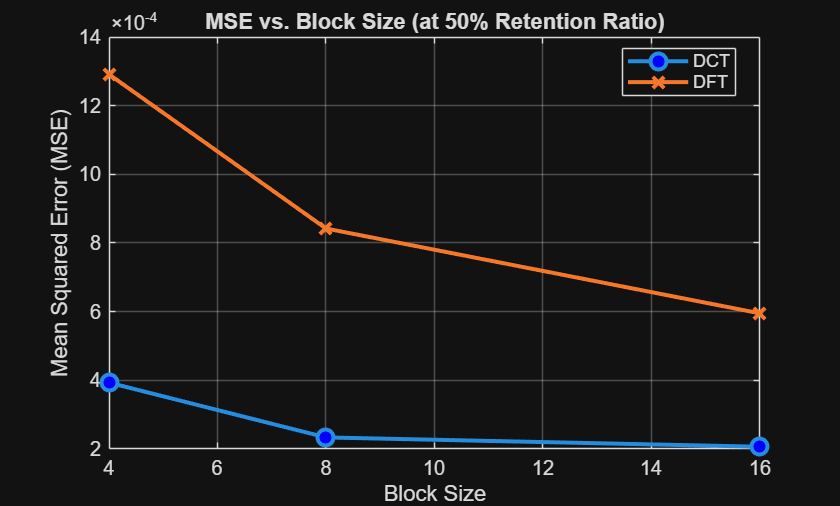

figure;
blockSizes_plot = [4, 8, 16];
mseDCT_50 = [mseDCT4_50, mseDCT8_50, mseDCT16_50];
mseDFT_50 = [mseDFT4_50, mseDFT8_50, mseDFT16_50];

plot(blockSizes_plot, mseDCT_50, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
plot(blockSizes_plot, mseDFT_50, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;

title('MSE vs. Block Size (at 50% Retention Ratio)');
xlabel('Block Size');
ylabel('Mean Squared Error (MSE)');
legend('DCT', 'DFT', 'Location', 'best');
grid on;

- Plot MSE vs. Retention Ratio (for 8x8 blocks)

figure;
retentionValues = [10, 25, 50];
mseDCT_8 = [mseDCT8_10, mseDCT8_25, mseDCT8_50];
mseDFT_8 = [mseDFT8_10, mseDFT8_25, mseDFT8_50];

plot(retentionValues, mseDCT_8, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
plot(retentionValues, mseDFT_8, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');

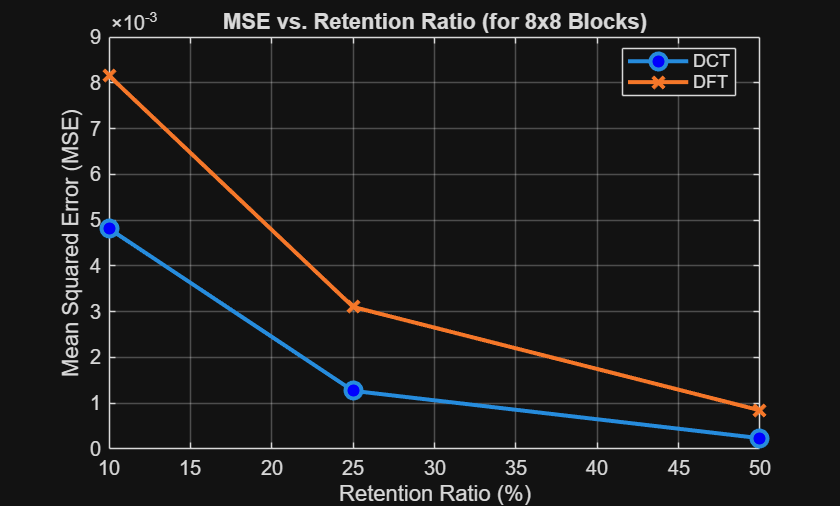

hold off;

title('MSE vs. Retention Ratio (for 8x8 Blocks)');
xlabel('Retention Ratio (%)');
ylabel('Mean Squared Error (MSE)');
legend('DCT', 'DFT', 'Location', 'best');
grid on;

### Section 6: Conclusion and Observations

- In both plots (retention and block size) vs MSE, DCT performed overall better than DFT as DCT has a better energy compaction. Meaning that the property we discussed in the introduction section where the DCT represents the signal with a low frequency cosine waves also affects the energy distribution, all the high energy compenents are bundles at the beginning of the "blocks" and the rest is approximatly zero which gives it an upper hand on DFT

- In the MSE vs Block size, it was also clear in the figures at 'SubSection 6' that the when the block size is increased the image becomes more washed or blurred as it averages out more details from the original image, but smaller blocks preserve finer details as they have less energy compaction unlike higher blocks which average out import details.

- effets of retention, as the retenion value increases the image becomes more clear and not washed. Which was seen in 'SubSection 6'. The affects are blurring and a grid like structure beginning to appear around areas where there were sharp jumps (high frequency) as the blocks didn't align perfectly, also in the DFT there was clear ghosting affect. Which after some research was called Gibbs phenomenon, happens due to the abrupt truncation of high frequency coefficients (high freq. sine waves).

# Bonus section:

for this section we are using the 8x8 divided image with retention ration of 25%.

selectedBlocks = compressedDCT8_25;
blockSize = 8;

TotalBlocks = 1024

[numBlockRows, numBlockCols] = size(selectedBlocks);
TotalBlocks = numBlockRows * numBlockCols

### SubSection 1: Zigzag Scanning

Convert all 2D blocks to 1D vectors using zigzag pattern

allData = [];
for i = 1:numBlockRows
    for j = 1:numBlockCols
        block = selectedBlocks{i, j};
        zigzagVec = zigzagScan(block);
        zigzagVec = round(zigzagVec); % Quantize
        allData = [allData, zigzagVec];
    end
end

TotalCoff = 65536


TotalCoff = length(allData)

### SubSection 2: Run-Length Encoding

Encode runs of repeated values

dataInt = int16(allData);
runs = [];
values = [];
currentVal = dataInt(1);
currentCount = 1;

for k = 2:length(dataInt)
    if dataInt(k) == currentVal
        currentCount = currentCount + 1;
    else
        runs = [runs, currentCount];
        values = [values, currentVal];
        currentVal = dataInt(k);
        currentCount = 1;
    end
end
runs = [runs, currentCount];
values = [values, currentVal];

RLE compression: 65536 coefficients -> 21548 symbols




fprintf('RLE compression: %d coefficients -> %d symbols\n\n', length(allData), length(values));

### SubSection 4: Huffman Encoding

Create symbols and apply Huffman coding

Create symbols by combining value and run length

symbols = cell(1, length(values));
for k = 1:length(values)
    symbols{k} = sprintf('%d_%d', values(k), runs(k));
end

Calculate symbol probabilities

uniqueSymbols = unique(symbols);
symbolCounts = histcounts(categorical(symbols), categorical(uniqueSymbols));
symbolProbs = symbolCounts / sum(symbolCounts);

Build Huffman dictionary

dict = huffmandict(uniqueSymbols, symbolProbs);

Encode using Huffman

encoded = huffmanenco(symbols, dict);

Encoded bitstream length: 156413 bits




fprintf('Encoded bitstream length: %d bits\n\n', length(encoded));

### SubSection 4: Compression Metrics

originalBits = 256 * 256 * 8;
compressedBits = length(encoded);
bpp = compressedBits / (256 * 256);
compressionRatio = originalBits / compressedBits;

Original size: 524288 bits (64.00 KB)


Compressed size: 156413 bits (19.09 KB)


fprintf('Original size: %d bits (%.2f KB)\n', originalBits, originalBits/8192);

Bits per pixel (bpp): 2.3867


fprintf('Compressed size: %d bits (%.2f KB)\n', compressedBits, compressedBits/8192);

Compression ratio: 3.35:1


fprintf('Bits per pixel (bpp): %.4f\n', bpp);

Space savings: 70.2%



fprintf('Compression ratio: %.2f:1\n', compressionRatio);
fprintf('Space savings: %.1f%%\n\n', (1 - compressedBits/originalBits) * 100);

### SubSection 5: Decoding Process

Huffman decoding

decodedSymbols = huffmandeco(encoded, dict);

RLE decoding

decodedData = [];
for k = 1:length(decodedSymbols)
    parts = strsplit(decodedSymbols{k}, '_');
    val = str2double(parts{1});
    run = str2double(parts{2});
    decodedData = [decodedData, repmat(val, 1, run)];
end

Reconstruct image blocks

coeffPerBlock = blockSize * blockSize;
idx = 1;
reconstructedImage = zeros(256, 256);

for i = 1:numBlockRows
    for j = 1:numBlockCols
        % Extract block coefficients
        blockData = decodedData(idx:idx+coeffPerBlock-1);
        idx = idx + coeffPerBlock;
        
        % Reshape to 2D block
        block2D = reshape(blockData, blockSize, blockSize)';
        
        % Apply inverse DCT
        spatialBlock = IDCT2(block2D);
        
        % Place in reconstructed image
        rowStart = (i-1) * blockSize + 1;
        colStart = (j-1) * blockSize + 1;
        reconstructedImage(rowStart:rowStart+blockSize-1, ...
                          colStart:colStart+blockSize-1) = real(spatialBlock);
    end
end

reconstructedImage = max(0, min(255, reconstructedImage));

### SubSection 6: Quality Assessment

mse = calculateMSE(resizedImageData, reconstructedImage);
psnr = 10 * log10(1 / mse);

Mean Squared Error (MSE): 0.043261


PSNR: 13.64 dB



fprintf('Mean Squared Error (MSE): %.6f\n', mse);
fprintf('PSNR: %.2f dB\n\n', psnr);

### SubSection 8: Visualization

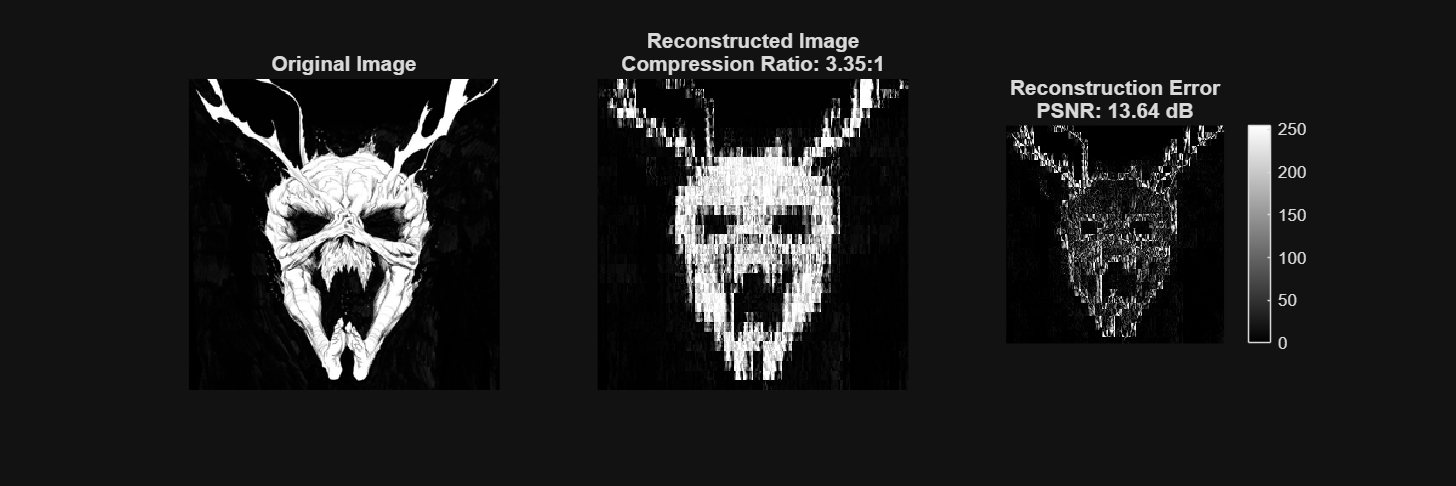

figure('Position', [100, 100, 1200, 400]);

subplot(1, 3, 1);
imshow(resizedImageData, []);
title('Original Image');

subplot(1, 3, 2);
imshow(reconstructedImage, []);
title(sprintf('Reconstructed Image\nCompression Ratio: %.2f:1', compressionRatio));

subplot(1, 3, 3);
errorImage = abs(double(resizedImageData) - reconstructedImage);
imshow(errorImage, []);

title(sprintf('Reconstruction Error\nPSNR: %.2f dB', psnr));
colorbar;

Average bits per pixel (bpp): 2.3867
Compression ratio: 3.35:1
PSNR: 13.64 dB


### SubSection: Summary for Report

fprintf('Average bits per pixel (bpp): %.4f\nCompression ratio: %.2f:1\nPSNR: %.2f dB\n', bpp, compressionRatio, psnr);

#### References:

- Oppenheim, A. V., Schafer, R. W., & Buck, J. R. (2009). *Discrete-Time Signal Processing* (3rd ed.)

- Gonzalez, R. C., & Woods, R. E. (2018). *Digital Image Processing* (4th ed.). Pearson.

- The MathWorks, Inc. (2023). *fft2 documentation*. https://www.mathworks.com/help/releases/R2025b/matlab/fourier-analysis-and-filtering.html?s_tid=CRUX_topnav